# Лабораторная работа №3

#### Решение СЛАУ методом вращений

Размер матрицы: 

clear
n = 10;

Число обусловленности:

alpha = 5;
[A, B, X0] = gen_matr(n, alpha);
MATR = [A B];
tic
X = rotation(MATR)';
toc

Elapsed time is 0.034088 seconds.


% X1 = rot(MATR, 10);
tic
[L, D, R] = LDR(A);
Z = inv(L)*B;
Z = inv(D)*Z;
X = inv(R)*Z;
toc

Elapsed time is 0.036407 seconds.


norm(X - X0)

ans = 1.3062e-11

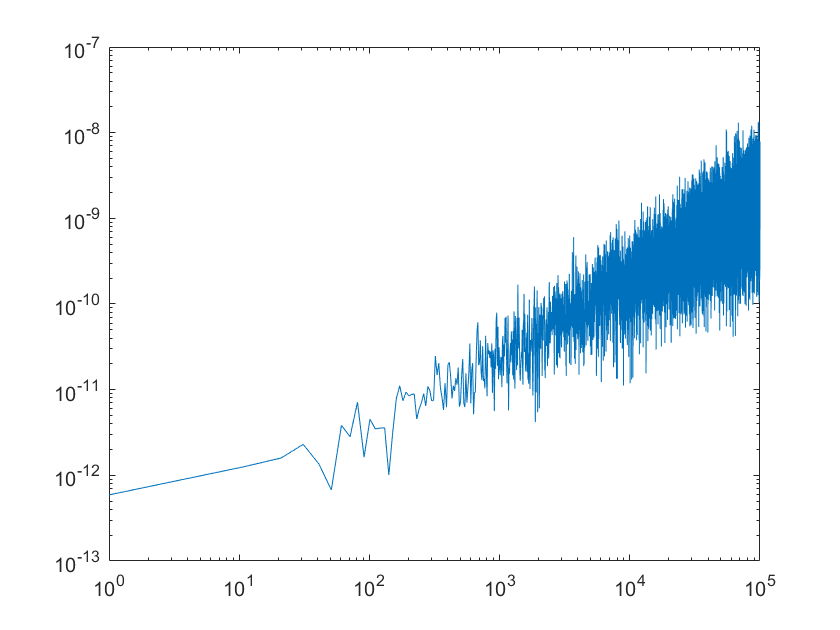


N = [];
NV = [];

X0 = [];
for j = 1:10
    X0(j) = randi(1000);
end
X0 = X0';
condd = 1:10:100000;
for i = 1:size(condd, 2)
%     A = gen_matr(10, condd(i));
    A = gallery('randsvd', n, condd(i));
    b = A * X0;
    A1 = [A b];
    X = rotation(A1)';
    N(i) = norm(X - X0);
    B = A*X;
    NV(i) = norm(b - B);
end
%semilogx(cond, N);
loglog(condd, N);

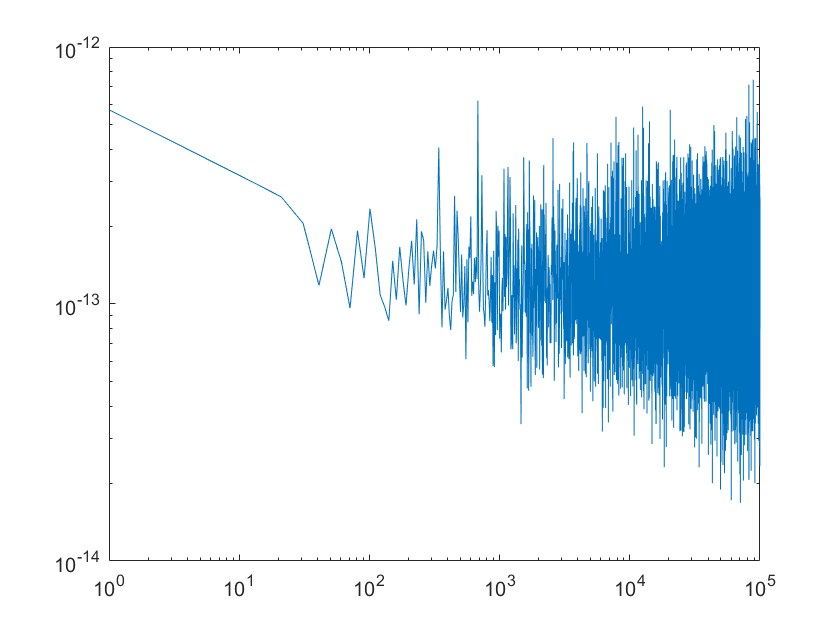

loglog(condd, NV);

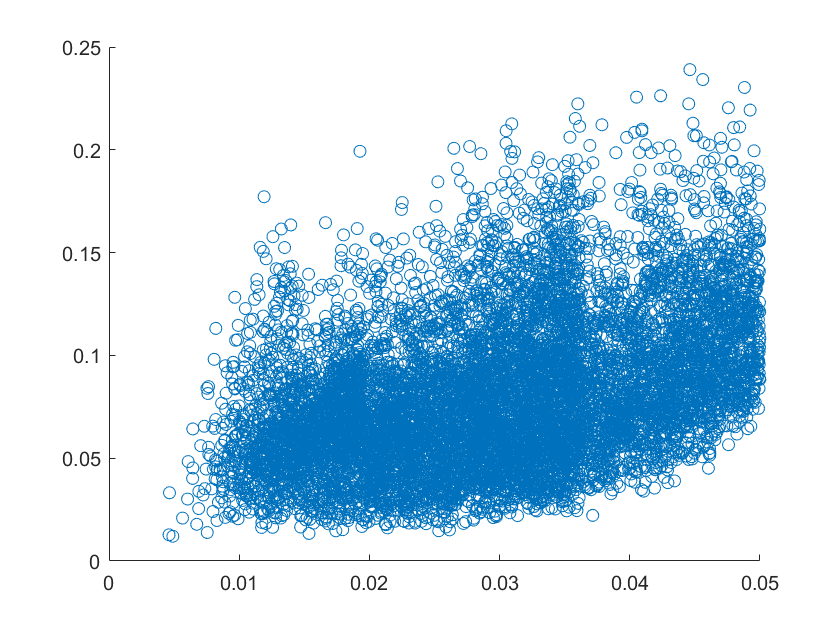


cc = 100;
DX = [];
DY = [];
A = gallery('randsvd', n, cc);
b = A * X0;
A1 = [A b];
X0 = rotation(A1)';
% X0 = matr_solve(A, b);
for i = 1:10000
    v = rand(10, 1);
    B = b + v.*b.*0.05;
    A1 = [A B];
    X = rotation(A1)';
%     X = matr_solve(A, B);
    DX(i) = norm(X0-X, Inf)/norm(X0, Inf);
    DY(i) = norm(v.*b.*0.05, Inf)/norm(b, Inf);
end

scatter(DY, DX);

function [A, B, V1] = gen_matr(n, alpha);
    D = eye(n);
    D(1, 1) = alpha;
    V = [];
    V1 = [];
    for i = 1:n
        V1(i) = randi(1000);
        V(i) = randi(1000);
%         V1(i) = rand();
%         V(i) = rand();
    end
    Q = eye(n) - 2*(V'*V)/(norm(V))^2;
    A = Q*D*Q';
    Ra = rand(n).*100;
    A = A + Ra;
    B = A*V1';
    V1 = V1';
end

function X = rotation(A)
    n = size(A, 1);
    for i = 1:n
        for j = i + 1:n
            c = A(i, i) / sqrt(A(i, i)^2 + A(j, i)^2);
            s = A(j, i) / sqrt(A(i, i)^2 + A(j, i)^2);
            for k = i:(n+1)
                el = A(i, k);
                A(i, k) = c * A(i, k) + s * A(j, k);
                A(j, k) = -s * el + c * A(j, k);
            end
        end
    end
    X = res(A);
end


function X = res(A)
    n = size(A, 1);
    X(n) = 0;
    for i = n:-1:1
        for k = i:n
            A(i, n + 1) = A(i, n + 1) - A(i, k) * X(k);
        end
        X(i) = A(i, n + 1) / A(i, i);
    end
end

function x = rot(MASS, n)
%Прямой ход метода вращений
for i = 2:n-1
    for j = i+1:n
        a = MASS(i,i);
        b = MASS(j,i);
        c = a/sqrt(a^2+b^2);
        s = b/sqrt(a^2+b^2);
        for k = i:n+1
            t = MASS(i,k);
            MASS(i,k) = (c*MASS(i,k)+s*MASS(j,k));
            MASS(j,k) = (-s*t+c*MASS(j,k));
        end
    end
end
x = zeros(n,1);
x(n) = MASS(n,n+1)/MASS(n,n);
for i = 1:n-1
    summ = 0;
    k = n-i;
    for j = k+1:n
        summ = summ + MASS(k,j)*x(j);
    end
    summ = MASS(k,n+1) - summ;
    if MASS(k,k) == 0
        disp('Negative');
    else 
        x(k) = summ/MASS(k,k);
    end
end
end

function [L, D, R] = LDR(A)
    n = length(A);
    [L, U] = lu(A);
    d = [];
    R = eye(n);
    L = eye(n);
    d(1) = A(1, 1);
    for i = 1:n
        O = 0;
        for j = 1:i-1
            O = O + L(i, j)*d(j)*R(j, i);
        end
        d(i) = A(i, i) - O;
        for z = (i+1):n
            O = 0;
            for j = 1:i-1
                O = O + L(z, j)*d(j)*R(j, i);
            end
            L(z, i) = (A(z, i) - O)/d(i);
        end
        for j = (i+1):n
            O = 0;
            for k = 1:i-1
                O = O + L(i, k)*d(k)*R(k, j);
            end
            R(i, j) = (A(i, j) - O)/d(i);
        end
    end
    D = diag(d, 0);
end

function X = matr_solve(A, B)
    [L, D, R] = LDR(A);
    Z = inv(L)*B;
    Y = inv(D)*Z;
    X = inv(R)*Y;
end